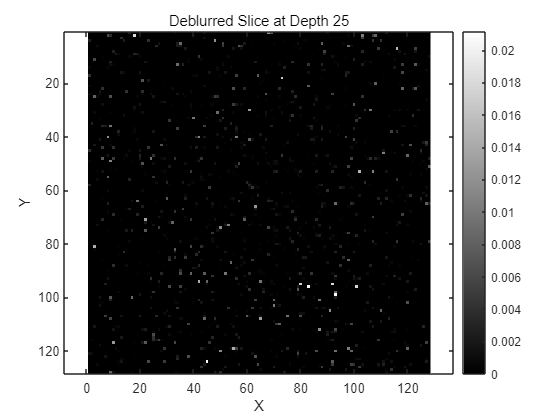

simblurNoNoise = load('simblurNoNoise.mat').blur;
psf = load('PSFG&Lsmall.mat').PSFsmall;

% 调整荧光强度，使图像像素的最终值不超过1
scale_factor = 1 / max(simblurNoNoise(:));
simblurNoNoise = simblurNoNoise * scale_factor;

% 添加背景噪声（高斯噪声）
noise_var = 0.01;
image_with_noise = imnoise(simblurNoNoise, 'gaussian', 0, noise_var);

% 确保图像像素值在0到1之间
image_with_noise(image_with_noise < 0) = 0;
image_with_noise(image_with_noise > 1) = 1;

% Richardson-Lucy 去卷积
numIterations = 40; % 迭代次数
deblurredImage = deconvlucy(image_with_noise, psf, numIterations);

% 显示去卷积后的一个切片图像
sliceToShow = 25; % 选择要显示的切片编号
deblurredSlice = deblurredImage(:, :, sliceToShow);

figure;
imagesc(deblurredSlice);
colormap gray;
colorbar;
axis equal;
title(['Deblurred Slice at Depth ', num2str(sliceToShow)]);
xlabel('X');
ylabel('Y');